Caso C1 método M1

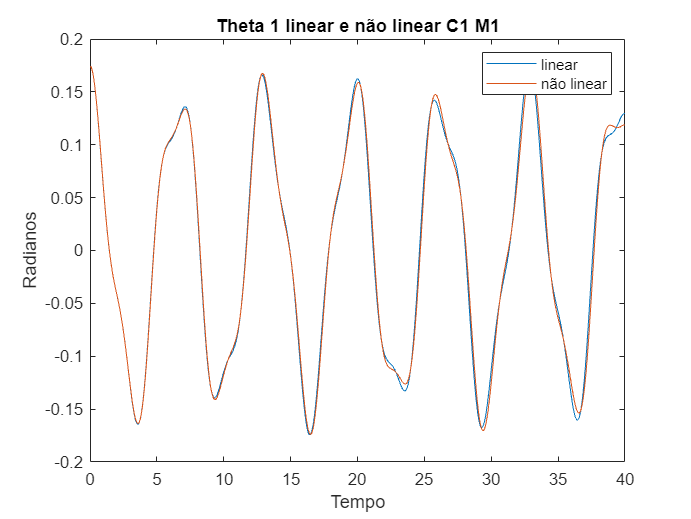

tempo =[0 100];
x0 =[(pi()/180)*10, (pi()/180)*5, 0, 0];
y0 =[(pi()/180)*10, (pi()/180)*5, 0, 0];
[t, xSol] = ode45(@edos, tempo, x0);
[t1, ySol] = ode45(@func, tempo, y0);


plot(t,xSol(:,1),t1,ySol(:,1))
title('Theta 1 linear e não linear C1 M1')
xlim([0 40])
xlabel('Tempo')
ylabel('Radianos')
legend('linear','não linear')

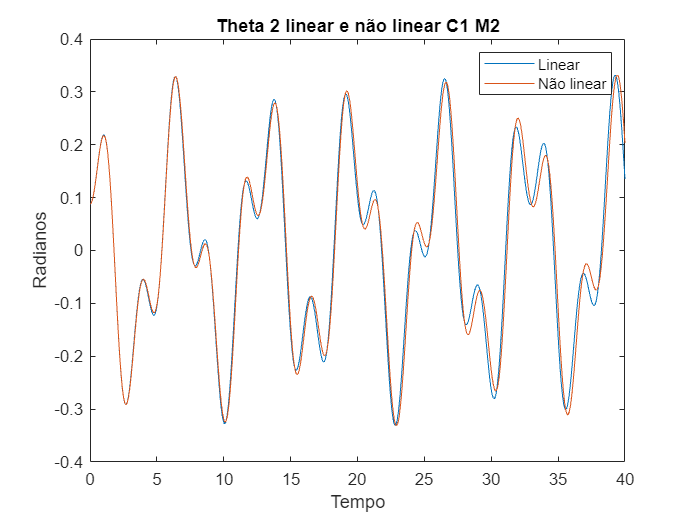



plot(t,xSol(:,2),t1,ySol(:,2))
title('Theta 2 linear e não linear C1 M2')
xlim([0 40])
xlabel('Tempo')
ylabel('Radianos')
legend('Linear','Não linear')

Caso C1 método M2

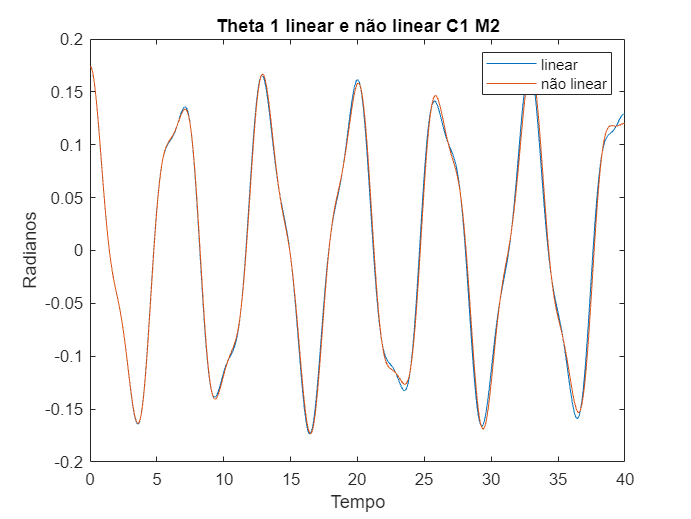

tempo =[0 100];
x0 =[(pi()/180)*10, (pi()/180)*5, 0, 0];
y0 =[(pi()/180)*10, (pi()/180)*5, 0, 0];
[t, xSol] = ode23(@edos, tempo, x0);
[t1, ySol] = ode23(@func, tempo, y0);


plot(t,xSol(:,1),t1,ySol(:,1))
title('Theta 1 linear e não linear C1 M2')
xlim([0 40])
xlabel('Tempo')
ylabel('Radianos')
legend('linear','não linear')

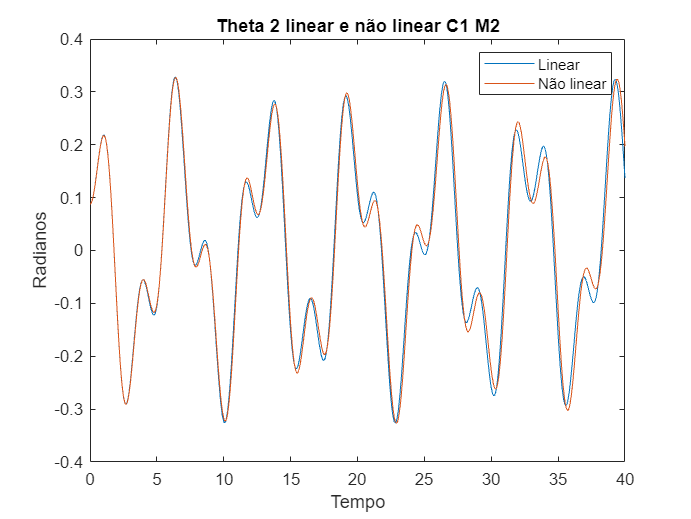



plot(t,xSol(:,2),t1,ySol(:,2))
title('Theta 2 linear e não linear C1 M2')
xlim([0 40])
xlabel('Tempo')
ylabel('Radianos')
legend('Linear','Não linear')

Caso C2 método M1

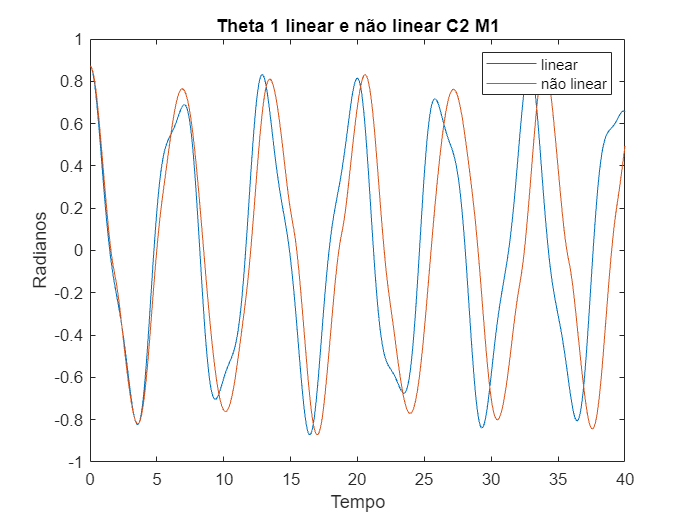

tempo =[0 100];
x0 =[(pi()/180)*50, (pi()/180)*30, 0, 0];
y0 =[(pi()/180)*50, (pi()/180)*30, 0, 0];
[t, xSol] = ode45(@edos, tempo, x0);
[t1, ySol] = ode45(@func, tempo, y0);


plot(t,xSol(:,1),t1,ySol(:,1))
title('Theta 1 linear e não linear C2 M1')
xlim([0 40])
xlabel('Tempo')
ylabel('Radianos')
legend('linear','não linear')

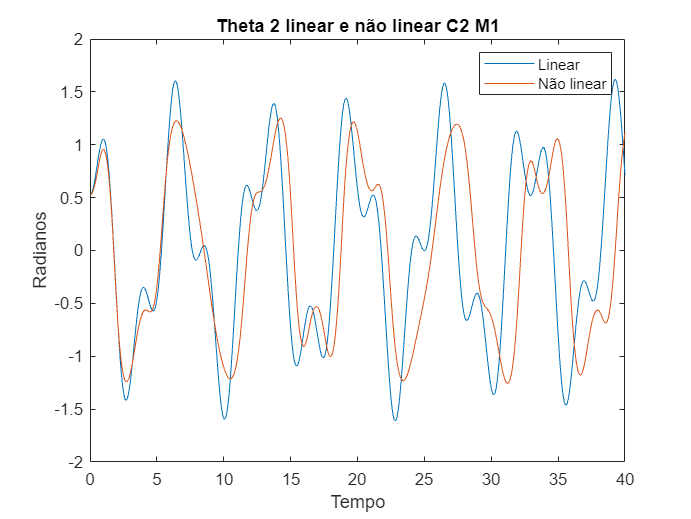



plot(t,xSol(:,2),t1,ySol(:,2))
title('Theta 2 linear e não linear C2 M1')
xlim([0 40])
xlabel('Tempo')
ylabel('Radianos')
legend('Linear','Não linear')

Caso C2 método M2

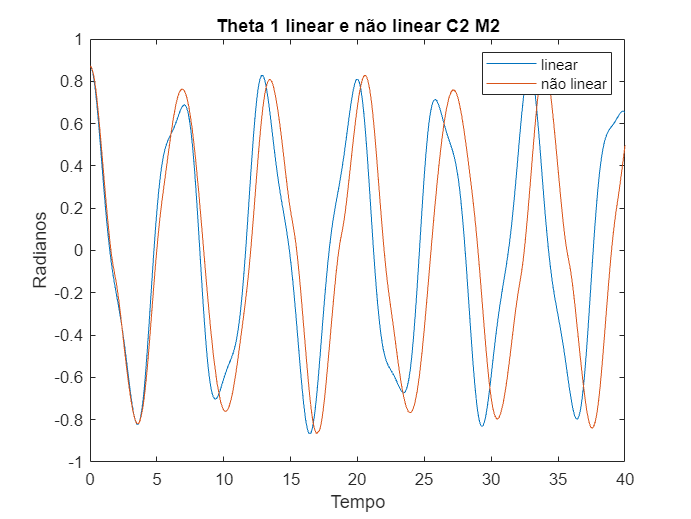

tempo =[0 100];
x0 =[(pi()/180)*50, (pi()/180)*30, 0, 0];
y0 =[(pi()/180)*50, (pi()/180)*30, 0, 0];
[t, xSol] = ode23(@edos, tempo, x0);
[t1, ySol] = ode23(@func, tempo, y0);


plot(t,xSol(:,1),t1,ySol(:,1))
title('Theta 1 linear e não linear C2 M2')
xlim([0 40])
xlabel('Tempo')
ylabel('Radianos')
legend('linear','não linear')

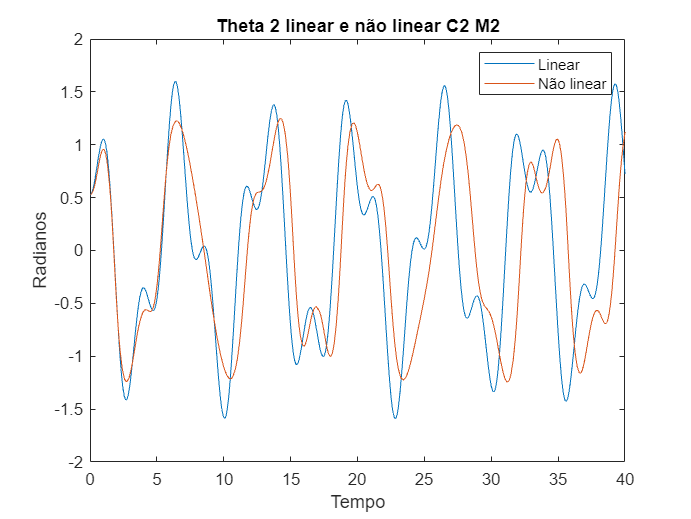



plot(t,xSol(:,2),t1,ySol(:,2))
title('Theta 2 linear e não linear C2 M2')
xlim([0 40])
xlabel('Tempo')
ylabel('Radianos')
legend('Linear','Não linear')

function dydt1 = func(t1,y) %n_linear
    omega_p = 1; lambda = 1.65;
          dydt1= [y(3);
                 y(4); %theta_2_p
                (6*lambda^2*omega_p^2*sin(y(1))/(-4*lambda^2 + 9*lambda*cos(y(1) - y(2))^2 - 12*lambda) + 12*lambda*omega_p^2*sin(y(1))/(-4*lambda^2 + 9*lambda*cos(y(1) - y(2))^2 - 12*lambda) - 9*lambda*omega_p^2*sin(y(2))*cos(y(1) - y(2))/(-4*lambda^2 + 9*lambda*cos(y(1) - y(2))^2 - 12*lambda) + 9*lambda*sin(y(1) - y(2))*cos(y(1) - y(2))*y(3)^2/(-4*lambda^2 + 9*lambda*cos(y(1) - y(2))^2 - 12*lambda) + 6*sin(y(1) - y(2))*y(4)^2/(-4*lambda^2 + 9*lambda*cos(y(1) - y(2))^2 - 12*lambda)); %theta_1_2p
                (-9*lambda^2*omega_p^2*sin(y(1))*cos(y(1) - y(2)))/(-4*lambda + 9*cos(y(1) - y(2))^2 - 12) + (6*lambda^2*omega_p^2*sin(y(2)))/(-4*lambda + 9*cos(y(1) - y(2))^2 - 12) - (6*lambda^2*sin(y(1) - y(2))*y(3)^2)/(-4*lambda + 9*cos(y(1) - y(2))^2 - 12) - (18*lambda*omega_p^2*sin(y(1))*cos(y(1) - y(2)))/(-4*lambda + 9*cos(y(1) - y(2))^2 - 12) + (18*lambda*omega_p^2*sin(y(2)))/(-4*lambda + 9*cos(y(1) - y(2))^2 - 12) - (18*lambda*sin(y(1) - y(2))*y(3)^2)/(-4*lambda + 9*cos(y(1) - y(2))^2 - 12) - (9*sin(y(1) - y(2))*cos(y(1) - y(2))*y(4)^2)/(-4*lambda + 9*cos(y(1) - y(2))^2 - 12)]; %theta_2_2p
 end


linear

function dxdt = edos(t,x) %linear
   omega_p= 1; lambda= 1.65;
        dxdt=  [x(3); %theta_1_p
                x(4); %theta_2_p
                (6*lambda^2*omega_p^2*x(1)  +  12*lambda*omega_p^2*x(1))/(-4*lambda^2-3*lambda) + (- 9*lambda*omega_p^2*x(2) )/(-4*lambda^2-3*lambda); %theta_1_2p
                (-9*lambda^2*omega_p^2*x(1) -   18*lambda*omega_p^2*x(1))/(-4*lambda-3) + (+ 6*lambda^2*omega_p^2*x(2)  +   18*lambda*omega_p^2*x(2) ) / (-4*lambda-3)]; %theta_2_2p
end
